format shortG
u = symunit;
% separateUnits(x)
% unitConvert(expr,units)

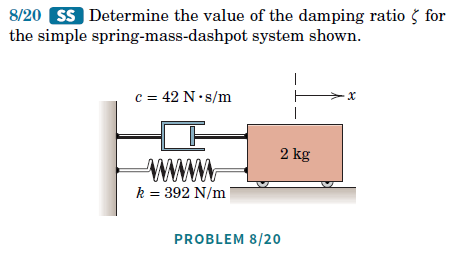

Vi kontroller først hvilken form for dæmpning vi har 

clear 

disp('Vi opstiller vores data')

Vi opstiller vores data


k = 392 % N/m    %* u.N / u.m

k =    392


m = 2 % kg      %* u.kg

m =      2


c = 42 %N*s/m   %* u.N * u.s / u.m

c =     42


disp('Egensvingningen findes')

Egensvingningen findes


w_n = sqrt(k/m) %egensvingningen

w_n =     14



disp('Dæmpningsrationen findes')

Dæmpningsrationen findes


zeta = c/(2 * m * w_n) % viscous damping factor or damping ratio

zeta =          0.75



if separateUnits(zeta) < 1
    disp('systemet er underdamped')
elseif separateUnits(zeta) == 1
    disp('systemet er critical damped')
else
    disp('systemet er overdamped')
end

systemet er underdamped



disp('Finder den naturlige dæmpnings frekvens')

Finder den naturlige dæmpnings frekvens


w_d = w_n*sqrt(1-zeta^2) % damped natrual freqancy

w_d =        9.2601



$$\tau_d = \frac{2\pi}{\omega_d} = \frac{2\pi}{\omega_n \sqrt{1 - \zeta^2}} $$
 

clear 

disp('Vi opstiller vores data')

Vi opstiller vores data


k = 800 % N/m    %* u.N / u.m

k =    800


m = 1 % kg      %* u.kg

m =      1


tau_d = 0.3          % Slut tiden

tau_d =           0.3


disp('Egensvingningen findes')

Egensvingningen findes


w_n = sqrt(k/m) %egensvingningen

w_n =        28.284



syms c

disp('Dæmpningsrationen findes')

Dæmpningsrationen findes


zeta = c/(2 * m * w_n) % viscous damping factor or damping ratio

$$zeta = \frac{\sqrt{2}\,c}{80}$$



disp('Finder den naturlige dæmpnings frekvens')

Finder den naturlige dæmpnings frekvens


w_d = w_n*sqrt(1-zeta^2) % damped natrual freqancy

$$w\_d = 20\,\sqrt{2}\,\sqrt{1-\frac{c^{2}}{3200}}$$


c_eq = tau_d == 2 * pi / w_d

$$c\_eq = \frac{3}{10}=\frac{\pi \,\sqrt{2}}{20\,\sqrt{1-\frac{c^{2}}{3200}}}$$

$$c\_sol = \left(\begin{array}{c} -1600\,\sqrt{\frac{1}{800}-\frac{\pi^{2}}{14400}}\\ 1600\,\sqrt{\frac{1}{800}-\frac{\pi^{2}}{14400}} \end{array}\right)$$


c = vpa(c_sol(2),3) %N*s/m   %* u.N * u.s / u.m

$$c = 38.0$$

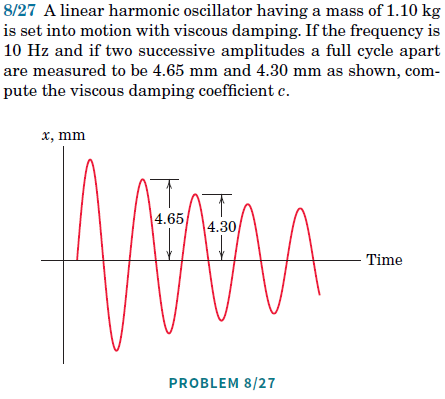

- benyt metode på side 267,

(8/29), 8/33 ,8/35